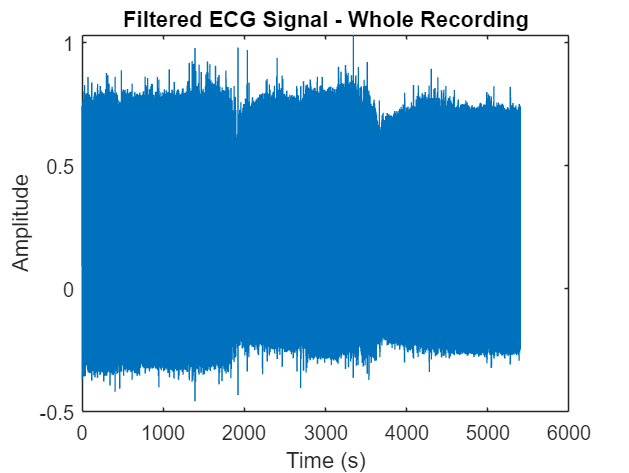

load('Placeholder.mat');

% Define the time axis
fs = 1000; % Specify the sampling frequency (in Hz) if you know it, otherwise use an appropriate estimate
time = (0:length(data)-1)/fs; 

% Design the bandpass filter
low_cutoff = 0.5; % Lower cutoff frequency (in Hz)
high_cutoff = 50; % Upper cutoff frequency (in Hz)
filter_order = 2; % Filter order
[b, a] = butter(filter_order, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');

% Apply the filter to the data
filtered_data = filtfilt(b, a, data);

% Plot the whole filtered ECG data
figure;
plot(time, filtered_data);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered ECG Signal - Whole Recording');

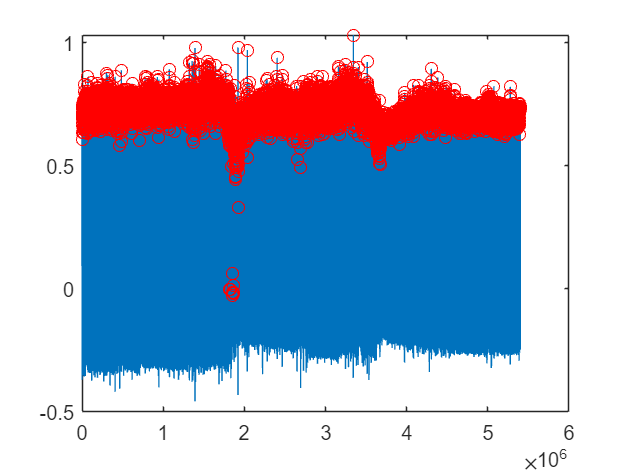


% Find Peaks
size(data,1)/1000/60;
[PKS,LOCS] = findpeaks(filtered_data,'MinPeakDistance',500);

% Plot Peaks
figure;plot(filtered_data);hold on;plot(LOCS,filtered_data(LOCS),'ro');

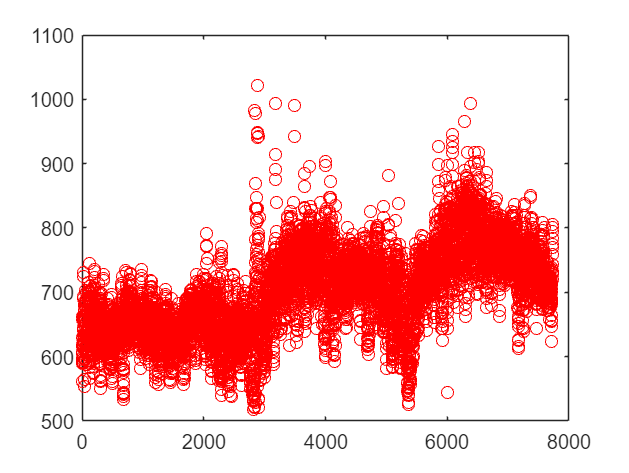

RR=diff(LOCS);

% Plot Time Differences
figure;plot(RR,'ro')